# Algorithm for 3D plot of system dynamics over a variable axis

## Creating a third perpendicular axis with a for loop (extending the dimension of the plot), plotting over the change of a determined control system parameter.

In this example, OTP is varied over time. This is using an special type of ADRC for first order system. Yet, the algoritm remains the same, using just diferent controller functions

clc, clear

n = 5 % Number of points to iterate over to

n = 5


c = 0.01 % 0.6748289; Initial Value

c = 0.0100


% Control system. Desired poles First Order Transfer Function
cs = tf(1,[1 2])


cs =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.



wc = 100

bo = 100


obs =
 
  A = 
           x1      x2
   x1  -122.2       1
   x2   -2061       0
 
  B = 
          u1     u2
   x1    100  122.2
   x2      0   2061
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



c = 0.0600

wc = 16.6667

bo = 16.6667


obs =
 
  A = 
           x1      x2
   x1  -134.4       1
   x2   -2408       0
 
  B = 
          u1     u2
   x1  16.67  134.4
   x2      0   2408
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



c = 0.1100

wc = 9.0909

bo = 9.0909


obs =
 
  A = 
           x1      x2
   x1  -148.7       1
   x2   -2837       0
 
  B = 
          u1     u2
   x1  9.091  148.7
   x2      0   2837
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



c = 0.1600

wc = 6.2500

bo = 6.2500


obs =
 
  A = 
           x1      x2
   x1  -165.5       1
   x2   -3374       0
 
  B = 
          u1     u2
   x1   6.25  165.5
   x2      0   3374
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



c = 0.2100

wc = 4.7619

bo = 4.7619


obs =
 
  A = 
           x1      x2
   x1  -185.5       1
   x2   -4056       0
 
  B = 
          u1     u2
   x1  4.762  185.5
   x2      0   4056
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



c = 0.2600

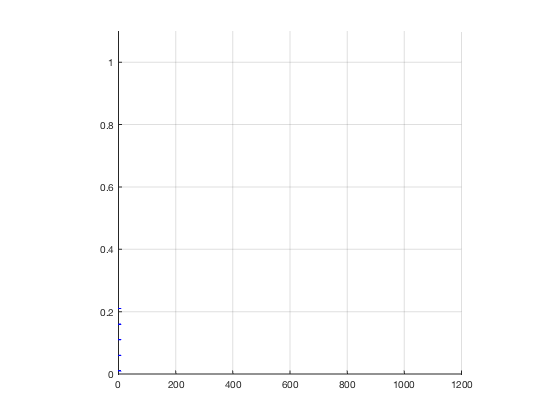

[A,B,C,D] = tf2ss(cell2mat(cs.Numerator),cell2mat(cs.Denominator));

for i=1:n
    % Controller function
    [wc,bo,obs] = otpADRC(cs,c)

    a = sim('Testbench_Algorithm');
    
    time = a.simout.Time;
    % time = downsample(time,100);
    % times (:,i) = time;
    z = c*ones(size(time));
    data = a.simout.Data;
    % data = downsample(data,100);
    % datas(:,i) = data;
    
    c = c + 0.05
    % tov = tov+1;
    
    axis([0 1200 0 1.1 0 220]);
    axis square,grid on,hold on
    plot3(time,z,data,'LineWidth',1,'Color','b')
end